# **Program** 2.1

# Convolution of two sequences

% The two discrete signals are x1 and x2

x1 = [1 2 0 1] ;
x2 = [2 2 1 1] ;

% y = x1 * x2 
 
y = conv(x1,x2) ;
disp('The convolution output is :')

The convolution output is :


disp(y)

     2     6     5     5     4     1     1



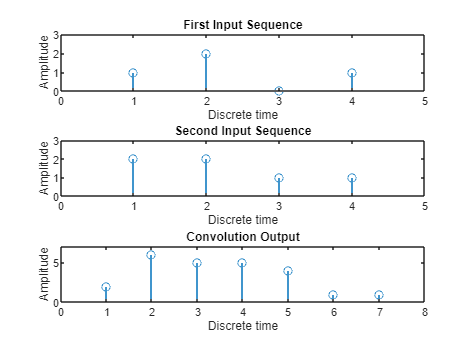


% Ploting sequence x1

subplot(3,1,1) ;
stem(x1) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('First Input Sequence') ;
axis([0 5 0 3]) ;

% Ploting sequence x2

subplot(3,1,2) ;
stem(x2) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Second Input Sequence') ;
axis([0 5 0 3]) ;

% Ploting Output sequence y

subplot(3,1,3) ;
stem(y) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Convolution Output') ;
axis([0 8 0 7]) ;

# Program 2.2

# Linear Convolution via Circular Convolution

x1 = [1 2 3 4 5] ;
x2 = [2 2 0 1 1] ;

x1e = [x1 zeros(1, length(x2)-1)] ;
x2e = [x2 zeros(1, length(x1)-1)] ;

ylin = cconv(x1e, x2e, length(x1e)) ;
disp('Linear convolution via circular convolution: ') ;

Linear convolution via circular convolution: 


disp(ylin) ;

    2.0000    6.0000   10.0000   15.0000   21.0000   15.0000    7.0000    9.0000    5.0000




y = conv(x1, x2) ;
disp('Direct Convolution: ') ;

Direct Convolution: 


disp(y) ;

     2     6    10    15    21    15     7     9     5

